clear;
load CrossVali_results.mat;
MethodsNames=["Env-LSTM","TF-LSTM","SS-LSTM","SS-MLR","SS-BP","SS-LSSVM"];

fold=6;
RMSE=zeros(fold+1,numel(CrossVali_results));
xPos=RMSE;
ErrMax=RMSE;
ErrMin=RMSE;
offsets=(-2.5:2.5)*0.133;
for i=1:numel(CrossVali_results)
    for j=1:fold
        RMSE(j,i)=mean(CrossVali_results{i}(j,:));
        ErrMax(j,i)=max(CrossVali_results{i}(j,:));
        ErrMin(j,i)=min(CrossVali_results{i}(j,:));
    end
    RMSE(end,i)=mean(mean(CrossVali_results{i}));
    ErrMax(end,i)=max(max(CrossVali_results{i}));
    ErrMin(end,i)=min(min(CrossVali_results{i}));
    xPos(:,i)=(1:7)'+offsets(i);
end

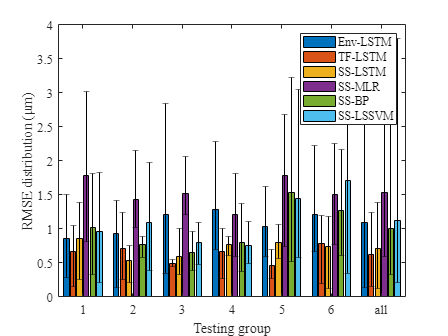

h=bar(RMSE);
xlabel("Testing group");
ylabel("RMSE distribution (μm)");
set(gca,'fontsize',12,'fontname','times new roman');
set(gca, 'xticklabels', {'1','2','3','4','5','6','all'});
hold on;  %在原图框上绘图，不再另起一个图框
errorbar(xPos,(ErrMax+ErrMin)/2,(ErrMax-ErrMin)/2,'k', 'Linestyle', 'None'); %添加误差棒
legend(h,MethodsNames);